#### **Part-1: Transfer function, poles & zeros and pole-zero diagram**

Fs = 5000;
T = 1/Fs;
a = [1 2 1];
b = [1 -1.2 0.75];

**1(a) Transfer Function H(z) of the system:**

H = tf(a,b,T,'variable','z^-1')

H =
 
     1 + 2 z^-1 + z^-2
  ------------------------
  1 - 1.2 z^-1 + 0.75 z^-2
 
Sample time: 0.0002 seconds
Discrete-time transfer function.



**1(b) Determination of poles and zeroes of the system:**

[zero,pole] = tf2zp(a,b)

zero =     -1
    -1


pole =    0.6000 + 0.6245i
   0.6000 - 0.6245i


**1(c) Pole-zero diagram of the system:**

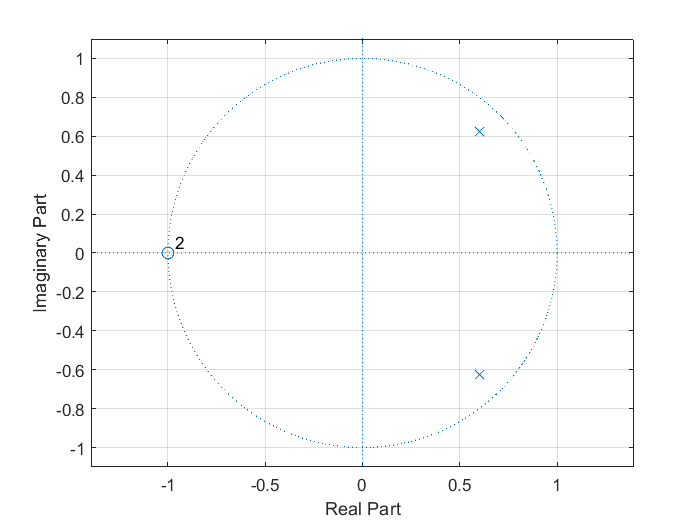

figure;
zplane(a,b);
grid on

#### Part-2: Frequency Response, frequency at maximum magnitude and Bandwidth

N = 512;
Fs = 5000;
Hz = freqz(a,b,N,'whole');
Mz = abs(Hz); % Magnitude response
Pz = angle(Hz); % Phase response
f = 0:Fs/(N-1):Fs;

**2(a) Frequency Response of the system:**

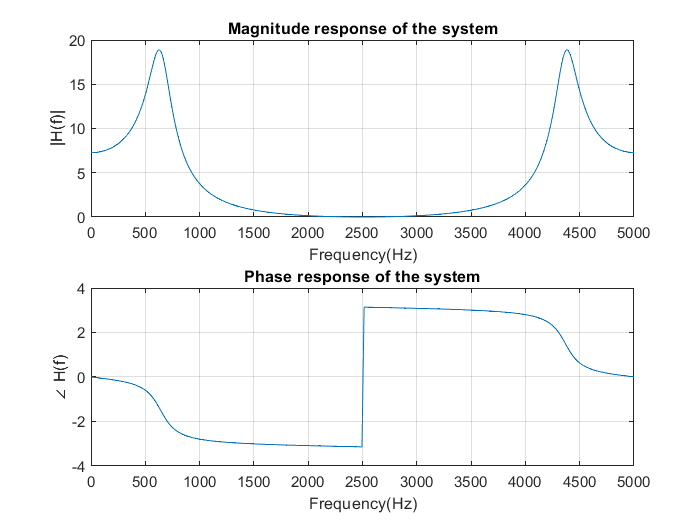

figure;
subplot(2,1,1)
plot(f, Mz);
title('Magnitude response of the system');
xlabel('Frequency(Hz)');
ylabel('|H(f)|')
grid on
subplot(2,1,2)
plot(f, Pz);
title('Phase response of the system');
xlabel('Frequency(Hz)');
ylabel('\angle H(f)')
grid on

**2(b) Frequency of maximum magnitude and Bandwidth of the system:**

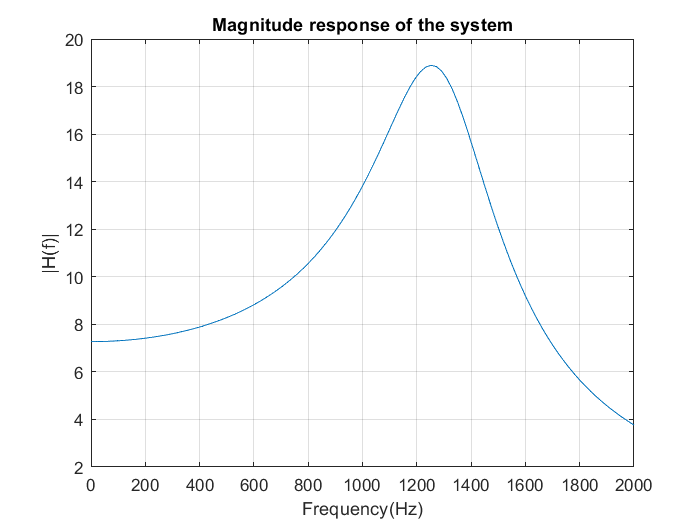

figure;
f = 0:Fs*2/(N-1):Fs*2;
plot(f, Mz);
xlim([0 2000])
title('Magnitude response of the system');
xlabel('Frequency(Hz)');
ylabel('|H(f)|')
grid on